- Load Audio

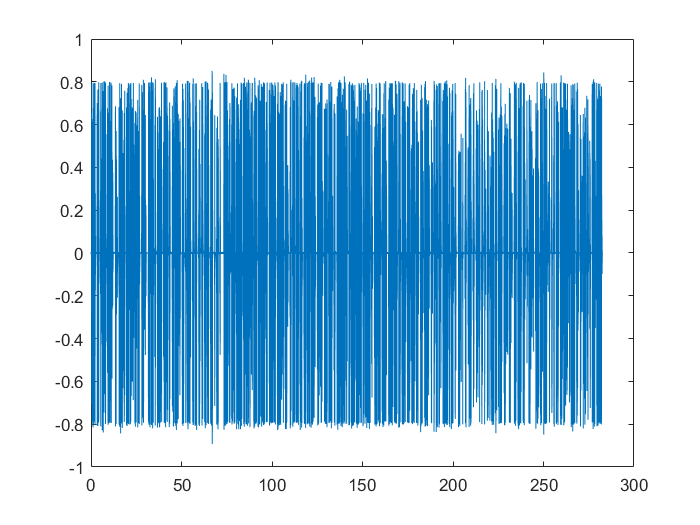

[orig_audio, orig_Fs] = audioread("audio_sample_2.mp3");
% downsample_ratio = 1;
% orig_audio = downsample(orig_audio, orig_Fs / downsample_ratio);
% orig_Fs = orig_Fs / downsample_ratio;
t = (1/orig_Fs) * (0:length(orig_audio)-1);
plot(t, orig_audio);

2. Generating Noise

% Adding noise
[noise_sample, noise_Fs] = audioread("noise_sample_4-blue_noise.wav")

noise_sample =          0
   -0.0050
   -0.0027
    0.0071
    0.0222
    0.0178
   -0.0002
   -0.0405
    0.0462
    0.0014


noise_Fs = 44100

noisy_audio = awgn(orig_audio, 35);
weakened_gen_noise = noisy_audio - orig_audio;
gen_noise = weakened_gen_noise';
% sound(noisy_audio, orig_Fs)
% noise_sample = downsample(noise_sample, orig_Fs);

% 
% if numel(noise_sample(:,1)) > numel(orig_audio)
%     rand_noise_index = randi(abs(numel(noise_sample(:,1)) - numel(orig_audio)) + 1, 1, 1);
%     gen_noise = noise_sample(rand_noise_index:rand_noise_index + numel(orig_audio) - 1);
% else
%     orig_audio = orig_audio(1:length(noise_sample));
%     gen_noise = noise_sample(:,1);
%     gen_noise = gen_noise';
%     t = t(1:length(noise_sample));
% end

% Correlated recording of environmental noise
noise_ref_mic_ratio = 1.2 % Simulate more "realistic" setup

noise_ref_mic_ratio = 1.2000

%Apply FIR filter to ensure correlation between noise and recording
firfilt = dsp.FIRFilter;
firfilt.Numerator = fir1(11,0.4);
f_noise = firfilt(gen_noise * noise_ref_mic_ratio)

f_noise = 	1.0e+-3 *

   -0.0494    0.0319    0.0448   -0.0094   -0.0243   -0.0477    0.0034    0.0331    0.0185   -0.0106   -0.0018    0.0155    0.0181   -0.0450   -0.0973   -0.0210   -0.0343    0.0628    0.0897   -0.0163    0.0231    0.0255    0.0289    0.0170   -0.0992    0.0311   -0.0379   -0.0438    0.0394   -0.0662   -0.0132   -0.0346    0.0254   -0.0246    0.0423    0.0283   -0.0637    0.0159    0.0093   -0.0524    0.0094   -0.0181    0.0413    0.0064   -0.0184   -0.0072    0.0372    0.0640    0.0259    0.0100


3. Adding Noise

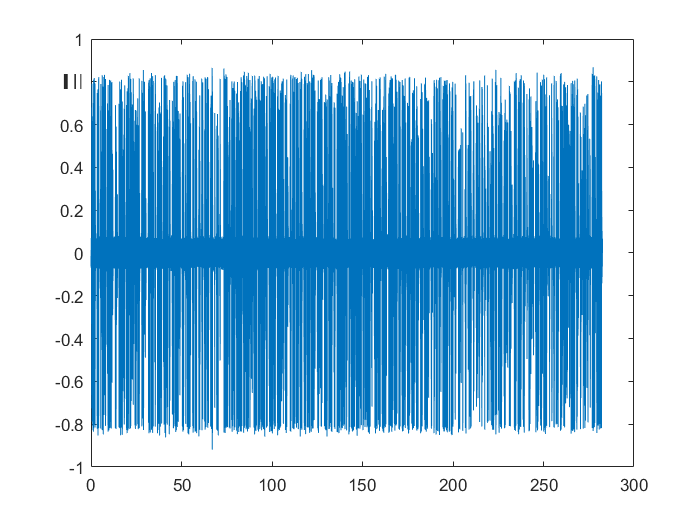

% orig_power = sum(orig_audio.^2);
% noise_weakness_factor = 30;
% noise_power = sum(gen_noise.^2) * noise_weakness_factor;
% weakened_gen_noise = sqrt(orig_power/noise_power) * gen_noise';
% noisy_audio = orig_audio + sqrt(orig_power/noise_power) * gen_noise';

% Frequency Analysis
% freq_values = fft(noisy_audio);
% noise_len = length(noisy_audio);          % number of samples
% f = (0:noise_len-1)*(orig_Fs/noise_len);     % frequency range
% power = abs(freq_values).^2/noise_len;
% plot(f, power)
% % sound(noisy_audio, orig_Fs);
% % sound(f_noise', orig_Fs)
% plot(t, f_noise);
plot(t, noisy_audio)

sound(noisy_audio, orig_Fs);


4. Butterworth Bandpass Filter

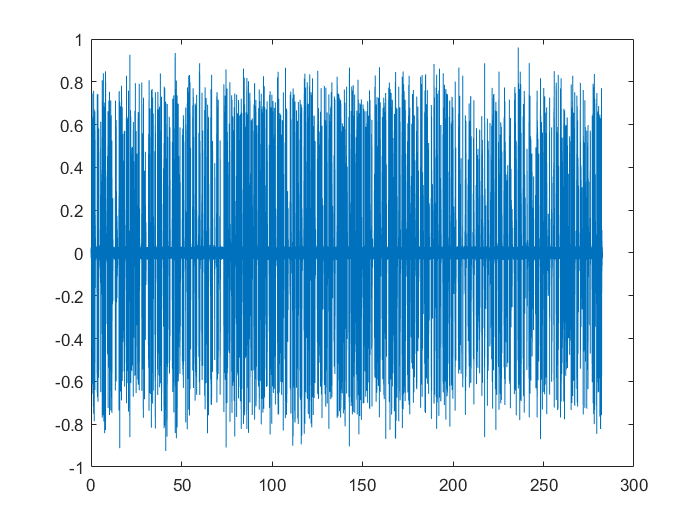

lower_freq = 200;
upper_freq = 4200;
% plot()
[b,a] = butter(5, [lower_freq,upper_freq] / (orig_Fs/2), "bandpass");
butter_audio = filter(b,a,noisy_audio);
plot(t, butter_audio)

snr_butter = snr(butter_audio, weakened_gen_noise)

snr_butter = 17.0939

% sound(butter_audio, orig_Fs)


5. Kaizer FIR Filter

% 
Fs = orig_Fs;  % Sampling Frequency

% Fstop1 = 200;      % First Stopband Frequency
% Fpass1 = 300;      % First Passband Frequency
% Fpass2 = 4000;     % Second Passband Frequency
% Fstop2 = 4100;     % Second Stopband Frequency
% Dstop1 = 0.001;    % First Stopband Attenuation
% Dpass  = 1;      % Passband Ripple
% Dstop2 = 0.001;    % Second Stopband Attenuation
% flag   = 'scale';  % Sampling Flag
% 
% % Calculate the order from the parameters using KAISERORD.
% [N,Wn,BETA,TYPE] = kaiserord([Fstop1 Fpass1 Fpass2 Fstop2]/(Fs/2), [0 ...
%                              1 0], [Dstop1 Dpass Dstop2]);
% 
% % Calculate the coefficients using the FIR1 function.
% b  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
% Hd = dfilt.dffir(b);
N    = 40;       % Order
Fc1  = 100;      % First Cutoff Frequency
Fc2  = 4200;     % Second Cutoff Frequency
flag = 'scale';  % Sampling Flag
Beta = 5;      % Window Parameter
% Create the window vector for the design algorithm.
win = kaiser(N+1, Beta);

% Calculate the coefficients using the FIR1 function.
b  = fir1(N, [Fc1 Fc2]/(Fs/2), 'bandpass', win, flag);
Hd = dfilt.dffir(b);

kaiser_audio = filter(b,1,noisy_audio);
snr_kaiser = snr(kaiser_audio, weakened_gen_noise)

snr_kaiser = 17.4180

% fzv = linspace(0, 1, 1000)*(Fs/2);                                          % Frequency Vector
% freqz(b, 1024, fzv, Fs)      
sound(kaiser_audio, orig_Fs);

6. Gaussian Filter

% median_audio = medfilt1(sgolay_audio,10);
% sound(sgolay_audio, orig_Fs);
gaussian_filter = gausswin(4);
gaussian_audio = filter(gaussian_filter, 1, kaiser_audio);
snr_gaussian = snr(gaussian_audio, weakened_gen_noise)

snr_gaussian = 20.9263

sound(gaussian_audio, orig_Fs);


7. Savitzky-Golay Filter (Smoothen)

order = 15;
frame_len = 21;
sgolay_audio = sgolayfilt(gaussian_audio, order, frame_len);
snr_sgolay = snr(sgolay_audio, weakened_gen_noise)

snr_sgolay = 20.9263


sound(sgolay_audio, orig_Fs);


8. LMS Noise Cancellation (Custom feature that requires noise reference (e.g. second mic))

% aaa


initial_coefficents = (firfilt.Numerator).'-0.01;
step = 0.05; 
lms = dsp.LMSFilter(12,'Method','Sign-Sign LMS',...
   'StepSize',step,'InitialConditions',initial_coefficents);
% sound(noisy_audio, orig_Fs)
[~, lms_audio] = lms(f_noise', noisy_audio);
% sound(lms_audio, orig_Fs)


Performance Metrics

% snr_orig = snr(orig_audio, weakened_gen_noise)
snr_filters = snr(sgolay_audio, weakened_gen_noise)

snr_filters = 20.9263

snr_lms = snr(lms_audio, weakened_gen_noise)

snr_lms = 18.2145

snr_noisy = snr(noisy_audio, weakened_gen_noise)

snr_noisy = 18.2796

% mse_filters = mean((orig_audio - gaussian_audio).^2)
% mse_lms = mean((orig_audio - lms_audio).^2)

% For white noise
var_filters = var(orig_audio - sgolay_audio)

var_filters = 0.0435

var_lms = var(orig_audio - lms_audio)

var_lms = 7.3421e-07

var_noisy = var(orig_audio - noisy_audio)

var_noisy = 3.1612e-04

% sound(noisy_audio, orig_Fs)
% snr_orig = snr(orig_audio, orig_Fs)
% snr_filters = snr(gaussian_audio, orig_Fs)
% snr_lms = snr(lms_audio, orig_Fs)